# 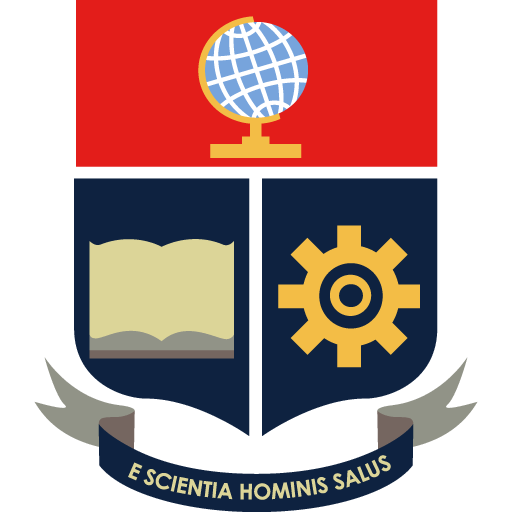Escuela Politécnica Nacional

#### `UTILIZACIÓN DEL SISTEMA DE RECONOCIMIENTO DE GESTOS EMPLEADO EN EL PROYECTO DE INVESTIGACIÓN PIGR-19-07 PARA EL COMANDO DE UN SISTEMA MULTI-AGENTE`

# **Comando del Sistema Multi-Agente**

## `Control de los agentes robóticos`

#### En base a:

**Modo 1: **Seguimiento de 3 agentes a un Líder Virtual

**Modo 2: **Seguimiento de 2 agentes a un agente Líder Seguidor

                  *Modo 1*                                *Modo 2*

      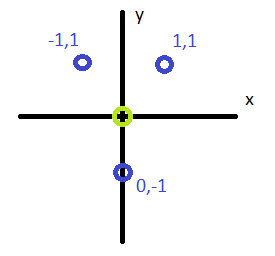   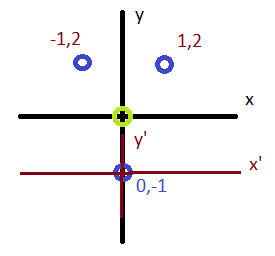

    mod=1;
if mod==1
    mssg="Modo 1 seleccionado";
    a=3;
    fprintf("|/| Modo 1")
elseif mod==2
    mssg="Modo 2 seleccionado";
    a=4;
    fprintf("Modo 2 |/|")
else
    a=1;
    mssg="Seleccionar modo";
end

|/| Modo 1

 "Modo 1 seleccionado";
  
% if mod==1     
%     waypoint1=[PosX1(length(PosX1)) PosY1(length(PosY1));x+rx1 y+ry1];
% elseif mod==2
     %en este caso a las posiciones rxi,ryi se les resta aquellas del agente
     % seguidor para que este se vuelva su referencia, siendo este el robot 2
% end


## 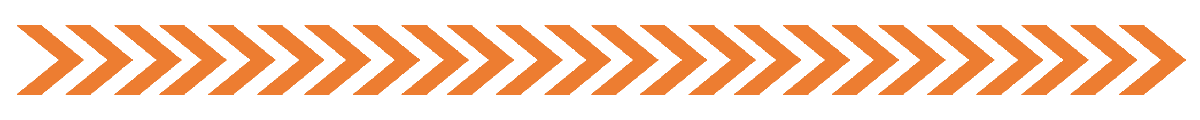

## `Selección de Acción por Referencia (sin HGR)`

- `Ejecutar en la otra Instancia de MATLAB el archivo para ingreso de comandos de referencia (Comando_main.mlx/"Referencia")`

## `Selección de Acción con el HGR`

- `Ejecutar en la otra Instancia de MATLAB el archivo del Sistema de Reconocimiento de Gestos (Comando_main.mlx/"HGR")`

option=6;
if server.NumBytesAvailable~=0
    data=read(server,server.NumBytesAvailable,"uint8");
    option=data(length(data));
end
ind=1;
% antniv=0;

while option~=3&&option~=4
    if server.NumBytesAvailable~=0
    data=read(server,server.NumBytesAvailable,"uint8");
    option=data(length(data));
    end

    if option==1%WaveOut
        niv=2;
        nivel="~Movimiento de trayectoria grupal         ";%42s
    elseif option==2%WaveIn
        niv=1;
        nivel="~Control de formación                     ";
    end
   
%     if antniv~=niv
        printStatus(nivel,ind)
        pause(0.1)
        ind=2;
%         antniv=niv;
%     end
end

Nivel seleccionado:
~Movimiento de trayectoria grupal         

 

if option==3%Fist
    if niv==1
        mov=0;
        open("menu_op1_formation.mlx")
%         run menu_op1_multiple.mlx;
    elseif niv==2
        mov=1;
        open("menu_op2.mlx")
    end
else %option==4
    open("Main.mlx")
end


function printStatus (mssg,ind)
     if ind == 1
        % The very first time we don't need to delete the old text
        % txt='Nivel seleccionado:\n';
        fprintf('Nivel seleccionado:\n')
        fprintf('%42s', mssg);
     else
        % Each \b removes one character from the previous fprintf.
        
        for i=1:42
             fprintf('\b');
        end
%         fprintf('\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b')
%         fprintf('\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\bNivel seleccionado:\n')
%         fprintf('\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b%32s', mssg);
        fprintf('%42s', mssg);
     end
end